# Gamma

Characterize the column gamma

Required variables

ol
cs

Create a comb for find gamma

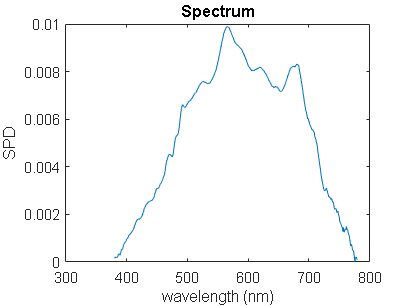

vec8_array = ones(8,1024);

col_center = [72 202 327 454 583 708 834 956];
wl_center = [400 450 500 550 600 650 700 750];

for i = 1:8
    j = col_center(i);
    vec8_array(i,j) = 1;
end

vec8_sum = sum(vec8_array,1);

ol.setColumn1024(vec8_sum)
mea_8 = cs.measure;

clf
mea_8.plot

Sweep the column amplitude

meascale = {}


meascale =

  0×0 empty cell array



vec_max = repmat([1],1,1024);
scale = 0:0.1:1;

for i = 1:length(scale)
    vec = vec_max * scale(i);
    ol.setColumn1024(vec)
    i
    mea = cs.measure;
    meascale{i} = mea;
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

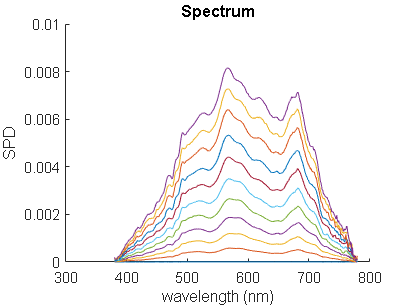

% visualize
clf
hold on
for i=1:length(scale)
    meascale{i}.plot
end

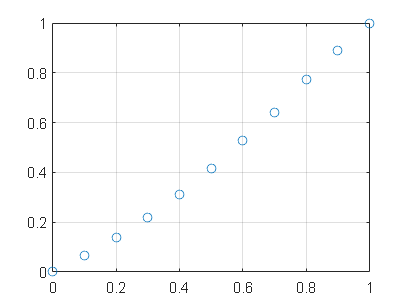

for i=1:length(scale)
    mea_net = meascale{i} - meascale{1};
    meaarea(i) = sum(mea_net.amplitude);
end
meaarea = meaarea / max(meaarea);

clf
plot(scale,meaarea,'o')
grid on

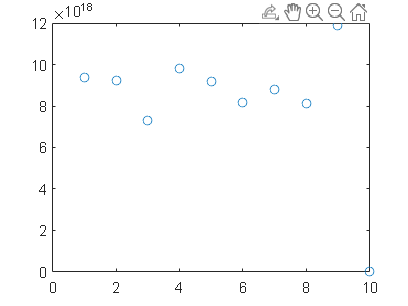

gamma_lut = zeros(11,2);
gamma_lut(:,1) = scale;
gamma_lut(:,2) = meaarea;

save('gamma_lut_HIMS1_06162022.mat','gamma_lut')